 clear all
 close all


## Construction du système discret

%dimensions du domaine
%ordre1
lx = 2;
ly = 2;

%nombre de points dans chaque dimension
Nx = 50;
Ny = 50;
% pas de discretisation
h = lx/(Nx+1);
k = ly/(1+Ny);

a = k^2/(2*(h^2 + k^2));
b = h^2/(2*(h^2 + k^2));
c = k^2*h^2/(2*(h^2 + k^2));

% construction du système linéaire
temp = a*ones(Nx-1,1);
A = eye(Nx) - diag(temp,1) - diag(temp,-1);
B = b*eye(Nx);

M = zeros(Nx*Ny);
M(1:Nx,1:Nx) = -eye(Nx);
M(1:Nx,Nx+1:2*Nx)= eye(Nx);
for i=2:Ny
    M((i-1)*Nx+1:i*Nx,(i-1)*Nx+1:i*Nx) = A;
    M((i-1)*Nx+1:i*Nx,(i-2)*Nx+1:(i-1)*Nx) = -B;
    if i < Ny
        M((i-1)*Nx+1:i*Nx,i*Nx+1:(i+1)*Nx) = -B;
    end
end
M

M =     -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0    -1     0     0     0     0     0     0     0     0     0     0     0   

%construction second membre
N = zeros(Nx*Ny,1);
x=linspace(h,lx,Nx);
y=linspace(k,ly,Ny);

for i=1:Nx
    N(i) = -k*g(x(i),lx,ly);
end

for j=2:Ny
    for i=1:Nx
        p = i + (j-1)*Nx;
        N(p)= N(p) - c*f(x(i),y(j),lx,ly);
    end 
end 

%résolution

U = M\N;
% affichage de la solution 
u=zeros(Nx+2,Ny+2);
Uth = u;
for i=1:Nx
    for j = 2:Ny
        p= i +(j-1)*Nx;
        u(i+1,j+1)=U(p,1);
        Uth(i+1,j+1) = uth(x(i),y(j),lx,ly);
    end
end
u

u =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.0072    0.0110    0.0147    0.0184    0.0221    0.0256    0.0291    0.0324    0.0356    0.0386    0.0415    0.0443    0.0468    0.0492    0.0514    0.0534    0.0552    0.0567    0.0581    0.0592    0.0600    0.0607    0.0611    0.0613    0.0612    0.0609    0.0604    0.0596    0.0586    0.0574    0.0560    0.0543    0.0525    0.0504    0.0482    0.0458    0.0432    0.0404    0.0375    0.0345    0.0314    0.0281    0.0248    0.0213    0.0179    0.0143    0.0108    0

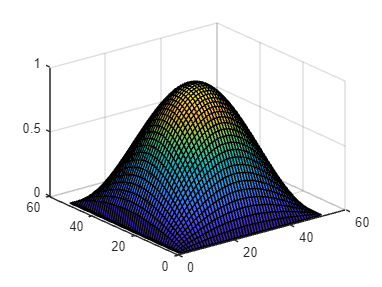

surf(u)


%erreur eps
eps = abs(u-Uth)

eps =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0004    0.0004    0.0004    0.0003    0.0003    0.0002    0.0002    0.0001    0.0000    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0009    0.0010    0.0012    0.0013    0.0015    0.0017    0.0019    0.0021    0.0023    0.0025    0.0028    0.0030   

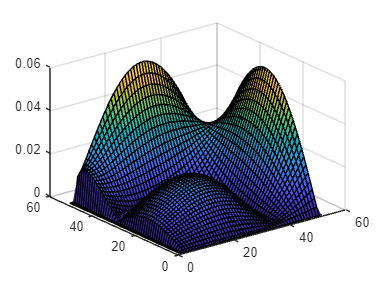

surf(eps);

N

N =     0.0038
    0.0076
    0.0115
    0.0153
    0.0190
    0.0226
    0.0262
    0.0296
    0.0330
    0.0362
